load parkingTrainGTFINISHED.mat gTruth
gTruth

gTruth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [3×5 table]
           LabelData: [400×3 table]



[imds,blds] = objectDetectorTrainingData(gTruth);
nFiles = length(imds.Files)

nFiles = 400

classes = categories(blds.LabelData{1,2})

classes = 3×1 cell array
    {'Accessible'}
    {'Charger'   }
    {'EV'        }


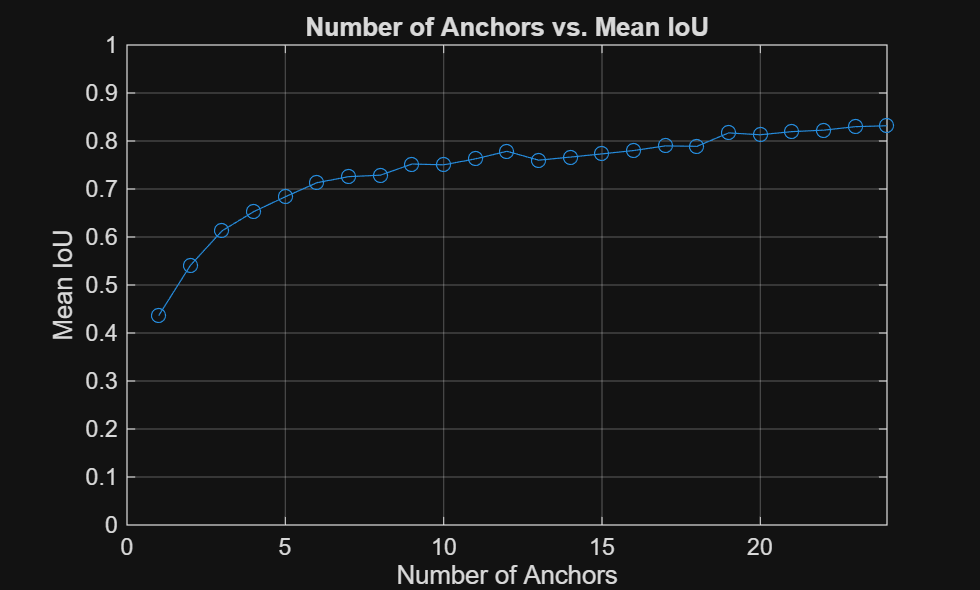


data = combine(imds,blds);

% estimating anchor boxes
maxAnchors = 24; 
meanIoU = zeros(maxAnchors, 1);
anchorBoxes = cell(maxAnchors, 1);

for idx = 1:maxAnchors
    [anchorBoxes{idx}, meanIoU(idx)] = estimateAnchorBoxes(data, idx);
end

% visualizing the results
plot(1:maxAnchors, meanIoU, "-o")
axis([0,maxAnchors,0,1])
grid
xlabel("Number of Anchors")
ylabel("Mean IoU")
title("Number of Anchors vs. Mean IoU")

*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* Accessible
* Charger
* EV

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _____    _________    ___________    _________    ____________    ______________
      1          1         00:00:40        0.001         4109.3           3589.7    
      1          5         00:01:43        0.001          2055            1688.6    
      2         10         00:02:55        0.001         868.74           780.98    
      3         15         00:04:06        0.001         474.61           443.56    
      4         20         00:05:18        0.001         415.64           277.74    
      5         25        

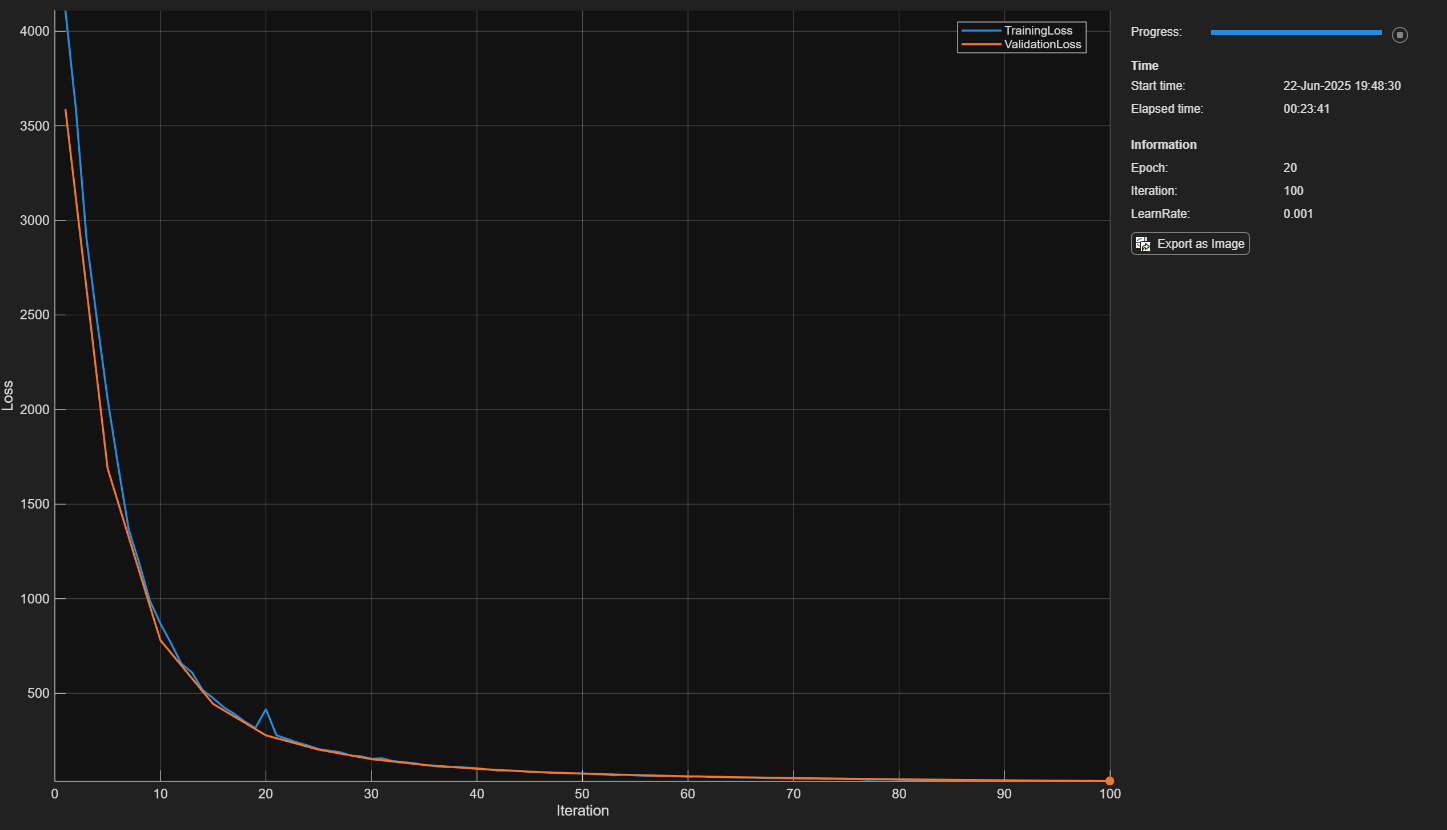

     20         100        00:23:34        0.001         35.441           35.958    

*************************************************************************
Detector training complete.
*************************************************************************



% splitting the dataset into training and validation sets
data = shuffle(data);
trainingFraction = 0.8;
numTraining = floor(nFiles*trainingFraction);
trainingData = subset(data, 1:numTraining);
validationData = subset(data, (numTraining+1):nFiles);

% building the detector
anchors = anchorBoxes{12};
anchorArea = anchors(:,1).*anchors(:,2);
[~, idx] = sort(anchorArea);
anchors = anchors(idx, :);trainingAnchors = cell(2, 1);
trainingAnchors{1} = anchors(1:6,:);
trainingAnchors{2} = anchors(7:12,:);
targetDataSize = [320 480 3]; 
detector = yolov4ObjectDetector("tiny-yolov4-coco",classes,trainingAnchors,"InputSize",targetDataSize);

% setting up training options and training the detector
options = trainingOptions("adam",...
    GradientDecayFactor=0.9,...
    SquaredGradientDecayFactor=0.999,...
    InitialLearnRate=0.001,...
    LearnRateSchedule="none",...
    MiniBatchSize=64,...
    L2Regularization=0.001,... 
    MaxEpochs=20,... 
    BatchNormalizationStatistics="moving",...
    DispatchInBackground=true,...
    ResetInputNormalization=false,...
    Shuffle="every-epoch",...
    VerboseFrequency=10,...
    Plots = "training-progress",...
    ValidationData=validationData,...
    ValidationFrequency=5,...
    OutputNetwork="best-validation-loss");

[detector,info] = trainYOLOv4ObjectDetector(trainingData,detector,options);

save('trained_yolov4_detector.mat', 'detector');
